# HW7

## Q2. B)

## u=G=0

dt = 0.5;
x = 0.045;
A = [0 1 0 0; 0 0 0 -x; 0 0 0 1; 0 x 0 0];
F = expm(A*dt);

F =     1.0000    0.5000         0   -0.0056
         0    0.9997         0   -0.0225
         0    0.0056    1.0000    0.5000
         0    0.0225         0    0.9997


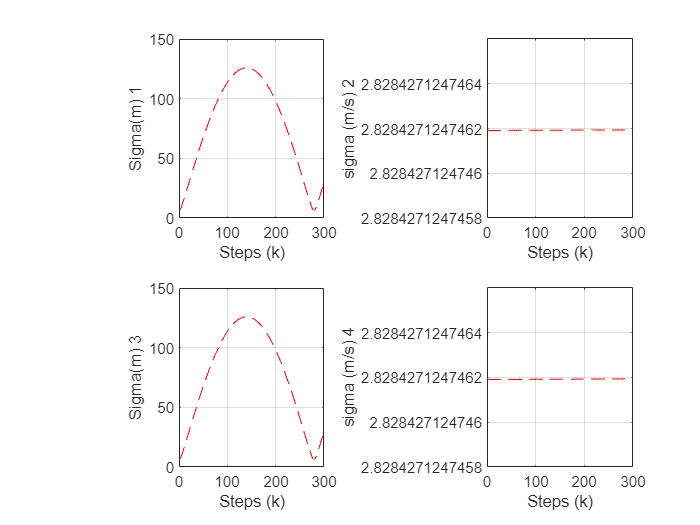

mean0 = [0; 60.104; 0; -60.104];
P0 = [10 0 0 0; 0 2 0 0; 0 0 10 0; 0 0 0 2];

meanT0 = [];
for n = 1:1:300
    meanN = (F^(n))*mean0;
    meanT0 = [meanT0; meanN];
end
meanT0;
mean_1 = [];
meanT0(1:4,:);
for i=1:4:1197
     a = meanT0(i,:)';
     mean_1 = horzcat(mean_1,a);
end
mean_1;

mean_2 = [];
for i=2:4:1198
     a = meanT0(i,:)';
     mean_2 = horzcat(mean_2,a);
end
mean_2;

mean_3 = [];
for i=3:4:1199
     a = meanT0(i,:)';
     mean_3 = horzcat(mean_3,a);
end
mean_3;

mean_4 = [];
for i=4:4:1200
     a = meanT0(i,:)';
     mean_4 = horzcat(mean_4,a);
end
mean_4;

covT = [];
for n = 1:1:300
    covN = F^(n)*P0*(F^(n))';
    covT = [covT,covN];
end
covT;
covN;
Mu = vertcat(mean_1,mean_2,mean_3,mean_4);

bounds_p2 = [];
for i=1:4:1200 
    bounds_pos = Mu(1:4,(i-1)/4+1) + 2*sqrt(diag(covT(1:4,i:3+i)));
    bounds_p2 = horzcat(bounds_p2,bounds_pos);
end
bounds_p2;
bounds_n2 = [];
for i=1:4:1200 
    bounds_neg = Mu(1:4,(i-1)/4+1) - 2*sqrt(diag(covT(1:4,i:3+i)));
    bounds_n2 = horzcat(bounds_n2,bounds_neg);
end
bounds_n2;

% Each state element of μ(k) versus time, along with ±2σ (2 standard deviations)
% upper/lower bounds

time = 1:1:300;

figure(1);
for i = 1:4
    subplot(2, 2, i);
    plot(time, Mu(i, :));
    hold on;
    plot(time,bounds_p2(i,:),'r--');
    hold on;
    plot(time,bounds_n2(i,:),'r--');
    hold off;
    xlabel('steps (k)');
    if mod(i,2) == 0
            ylabel(['X(m/s) ' num2str(i)]);
        else
            ylabel(['X(m) ' num2str(i)]);
    end
    grid on;

end 
bounds_only=[];
for i=1:4:1200 
    bounds_2 = 2*sqrt(diag(covT(1:4,i:3+i)));
    bounds_only = [bounds_only, bounds_2];
end

figure(2);
for i = 1:4
    subplot(2, 2, i);
    plot(time,bounds_only(i,:),'r--');
    xlabel('Steps (k)');
    if mod(i,2) == 0
            ylabel(['sigma (m/s) ' num2str(i)]);
        else
            ylabel(['Sigma(m) ' num2str(i)]);
    end
    grid on;
end

We can see in the plot for the 1st half of sigma1 & sigma3 the stdandard deviation is growing as expected with no process or measurement noise and decreases back to zero as the states return to their initial condition, as the states start to move ahead the standard deviation again starts to grow again.

## Q3. C)

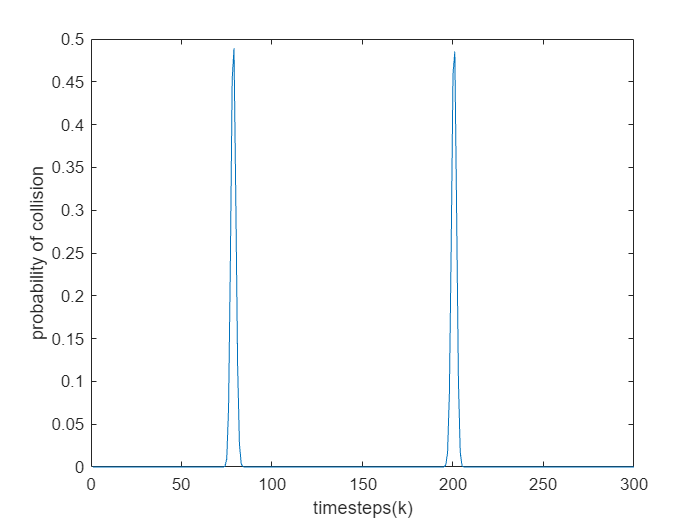

dt = 0.5;
xa = 0.045;
A = [0 1 0 0; 0 0 0 -xa; 0 0 0 1; 0 xa 0 0];
Fa = expm(A*dt);

dt = 0.5;
xb = -0.045;
A = [0 1 0 0; 0 0 0 -xb; 0 0 0 1; 0 xb 0 0];
Fb = expm(A*dt);

Mu_a0 = [0; 85*cos(pi/4); 0; -85*sin(pi/4)];
Pa0 = diag([10, 4, 10, 4]);
Mu_b0 = [3200; 85*cos(pi/4); 3200; -85*sin(pi/4)];
Pb0 = diag([11,3.5,11,3.5]);

for n = 1:1:300
    mean = (Fa^(n))*Mu_a0 - (Fb^(n))*Mu_b0;
    meanP = [mean(1) mean(3)];
    cov = Fa^(n)*Pa0*(Fa^(n))'+ Fb^(n)*Pb0*(Fb^(n))';
    covP = [cov(1,1),cov(1,3);cov(3,1),cov(3,3)];
    p(n) = mvncdf([-100, -100],[100, 100],meanP,covP);
end
p;
k = 1:300;
figure(3);
plot(k, p)
xlabel('timesteps(k)')
ylabel('probability of collision')

Q1) In particular, at what time steps are the vehicles in greatest danger of colliding?

A1-> Maximum danger occurs at time step 79 and 201, so time = 0.5*79, 0.5*201 .

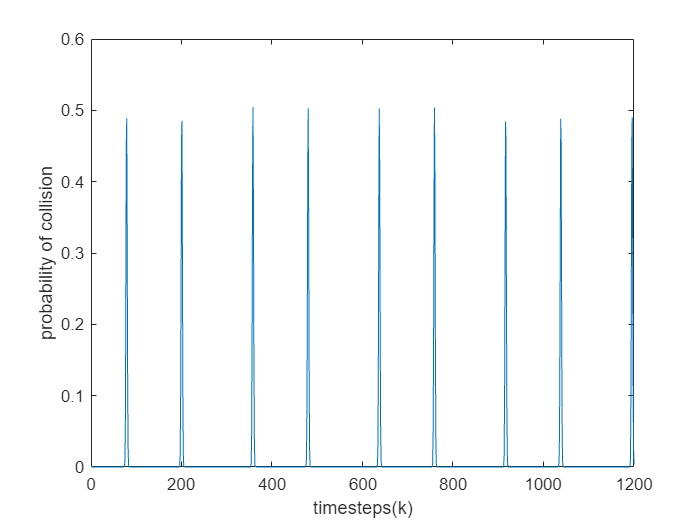

for n = 1:1:1200
    mean = (Fa^(n))*Mu_a0 - (Fb^(n))*Mu_b0;
    meanP = [mean(1) mean(3)];
    cov = Fa^(n)*Pa0*(Fa^(n))'+ Fb^(n)*Pb0*(Fb^(n))';
    covP = [cov(1,1),cov(1,3);cov(3,1),cov(3,3)];
    p1(n) = mvncdf([-100, -100],[100, 100],meanP,covP);
end
k1 = 1:1200;
figure(4);
plot(k1, p1)
xlabel('timesteps(k)')
ylabel('probability of collision')

Q2) Also, what happens to the probability of collision as time increases? What explains this behavior?

A2-> The probability of collision remains the same it does not increase or decrease due to the behaviour of states is like a sinusoidal curve, and probability can never be negative.